## Primeira tentativa -- abordagem mais direta

Nessa situação abordada a gente em princípio assume que o coeficiente de arrasto ($\left.\beta \text{ }\right)$e a gravidade ($g$) são conhecidos e constantes. Nesse cenário, em cima da equação da dinâmica levantada, tem-se que:


$$\ddot{x}= \frac{0,0034ge^{-x/22000}\dot{x}^2}{2\beta} - g $$


Tomando essa equação por base, podemos tentar reescrever o sistema no espaço de estados (não-linear), em que serão considerados dois estados (a máxima orda da minha equação diferencial é de 2º ordem) . Arbitrarei para este problema os estados:


$$\begin{array}{l}
x_1 =x\\
x_2 =\dot{x} 
\end{array}$$


Sendo assim, tentanto reespressar a equação de dinâmica não-linear, tem-se que:


$$\dot{\text{ }x_1 } =\dot{\text{ }x} =x_2$$



$$\dot{x_2} = \frac{0,0034ge^{-x/22000}\dot{x}^2}{2\beta} - g = \frac{0,0034ge^{-x_1/22000}x_2^2}{2\beta} - g $$


Isso obviamente depois de reescrever as equações e trocar os respectivos valores para os estados arbitrados.

Feito isso, no futuro teremos de encontrar as matrizes de estados linearizadas no entorno das melhores estimativas dos estados possíveis. A ideia então é proceder com a determinação da matriz $F$do sistema (aproximação de Taylor de 1º ordem).

Com a finalidade de simplificação, eu irei chamar as equações da forma:

 
$$\begin{array}{l}
f_1 =\dot{\text{ }x_1 } \\
f_2 =\dot{\text{ }x_2 } 
\end{array}$$


Com isso, a determinação da matriz $F$, tem-se que:


$$F = \left.\frac{\partial f(x)}{\partial x}\right|_{x = \hat{x}}
$$


Para para o caso de 2º ordem é dada por:


$$F=\left\lbrack \begin{array}{c}
\frac{\text{ }\partial \text{ }f_1 }{\partial \text{ }x_1 }\text{ } & \frac{\text{ }\partial \text{ }f_1 }{\partial \text{ }x_2 }\\
\frac{\text{ }\partial \text{ }f_2 }{\partial \text{ }x_1 } & \frac{\text{ }\partial \text{ }f_2 }{\partial \text{ }x_2 }
\end{array}\right\rbrack$$


Sendo assim, teremos de determinar as derivadas acima:

- 
$$\frac{\text{ }\partial \text{ }f_1 }{\partial \text{ }x_1 }=\frac{\text{ }\partial \text{ }\dot{\text{ }x_1 } }{\partial \text{ }x_1 }=\frac{\text{ }\partial \text{ }x_2 }{\partial \text{ }x_1 }=0$$


- 
$$\frac{\text{ }\partial \text{ }f_1 }{\partial \text{ }x_2 }=\frac{\text{ }\partial \text{ }\dot{x_1 \text{ }} }{\partial \text{ }x_2 }=\frac{\text{ }\partial \text{ }x_2 }{\partial \text{ }x_2 }=1$$


- $\frac{\text{ }\partial \text{ }f_2 }{\partial \text{ }x_1 }=\frac{\text{ }\partial \text{ }\dot{\text{ }x_2 } }{\partial \text{ }x_1 }$=$\frac{\text{ }\partial \text{ }\left(\frac{\text{ }0,0034{\mathrm{ge}}^{\frac{-x_1 }{22000}} x_2^2 }{2\beta \text{ }}-g\right)}{\partial \text{ }x_1 }=$$-\frac{\text{ }0,0034{\text{ge}}^{\frac{{-x}_1 }{22000}} x_2^2 }{44000\beta \text{ }}$

- $\frac{\text{ }\partial \text{ }f_2 }{\partial \text{ }x_2 }=\frac{\text{ }\partial \text{ }\dot{\text{ }x_2 } }{\partial \text{ }x_2 }$=$\frac{\text{ }\partial \text{ }\left(\frac{\text{ }0,0034{\text{ge}}^{\frac{-x_1 }{22000}} x_2^2 }{2\beta \text{ }}-g\right)}{\partial \text{ }x_2 }=\frac{\text{ }0,0034{\mathrm{ge}}^{\frac{-x_1 }{22000}} x_2 }{\beta \text{ }}$

Em tese já temos a nossa matriz $F$não linear, que é dada por:


$$F\left(t\right)=\left\lbrack \begin{array}{c}
0 & 1\\
-\frac{\text{ }0,0034{\text{ge}}^{\frac{{-x}_1 }{22000}} x_2^2 }{44000\beta \text{ }} & \frac{\text{ }0,0034{\text{ge}}^{\frac{-x_1 }{22000}} x_2 }{\beta \text{ }}
\end{array}\right\rbrack$$


que, por simplificação, será denominada por:


$$F\left(t\right)=\left\lbrack \begin{array}{c}
0 & 1\\
f_{21}  & f_{22} 
\end{array}\right\rbrack$$


A nossa dinâmica final, linearizada (ponto a ponto) será algo da forma:


$$\left\lbrack \begin{array}{c}
\dot{\text{ }x_1 } \\
\dot{\text{ }x_2 } 
\end{array}\right\rbrack =$$

$$\left\lbrack \begin{array}{c}
0 & 1\\
f_{21}  & f_{22} 
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
x_1 \\
x_2 
\end{array}\right\rbrack +\left\lbrack \begin{array}{c}
0\\
u_s 
\end{array}\right\rbrack$$


em que a gente supõe um erro na modelagem da dinâmica da aceleração (um ruído), pois o nosso modelo pode ter um erro na dinâmica da aceleração. Esse erro tem média zero.

Como dito logo acima, a gente considera a coeficiente de arrasto e aceleração da gravidade como sabidos e constantes. Dito isto, vamos agora determinar as equações do nosso sistema que serão utilizadas no filtro de Kalman.

A primeira coisa é determinar quem que é a matriz $\Phi \text{ }\left(t\right)$, que é dada por:


$$\Phi(t)=I+Ft+\frac{F^2t^2}{2!} +\frac{F^3t^3}{3!} + \dots$$


Na discretização, apenas a matriz $\Phi_k$entra nas equações de RIccati. E como visto ainda no capítulo 5, a gente não precisa determinar todos os termos dessa série. A ideia inicial é fazermos uma aproximação e pegaremos apenas os 2 primeiros termos. Assim, tem-se que:


$$\Phi \left(t\right)\approx I+F\text{t}=\left\lbrack \begin{array}{c}
1 & t\\
f_{21} t & \left(1+f_{22} t\right)
\end{array}\right\rbrack$$


e discretizando, tem-se que:


$$\Phi_k \approx I+{F\text{T}}_s =\left\lbrack \begin{array}{c}
1 & T_s \\
f_{21} T_s  & \left(1+f_{22} T_s \right)
\end{array}\right\rbrack$$


em que $T_s$ é o tempo de amostragem. 

Ademais, importante lembrar que a nossa medida se dará apenas por meio de uma medida de distância (com ruído), de forma que:


$$x_k^∗ =\left\lbrack \begin{array}{c}
1 & 0
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
x_1 \\
x_2 
\end{array}\right\rbrack +v_k$$
 

Ou seja, a nossa matriz $H$do sistema já é linear (não precisa passar por linearização). De posse dessas informações iniciais, a gente consegue então determinar a matriz $R_k$, que é dada por:


$$R_k =E\left\lbrack v_k v_k^T \right\rbrack =\sigma_v^2$$


Vamos agora tentar determinar quem que é a matriz $Q_k$, por meio de:


$$Q_k = \int_{0}^{T_s}\Phi(\tau)\textbf{Q}\Phi^{T}(\tau) d\tau$$


em que:


$$Q=E\left\lbrack w_k w_k^T \right\rbrack =E\left\lbrack \left\lbrack \begin{array}{c}
0\\
u_s 
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
0 & u_s 
\end{array}\right\rbrack \right\rbrack =E\left\lbrack \begin{array}{c}
0 & 0\\
0 & u_s^2 
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
0 & 0\\
0 & E\left\lbrack u_s^2 \right\rbrack 
\end{array}\right\rbrack$$


como o erro de modelagem é assumido gaussiano de média zero ($\eta =0$), tem-se que:


$$\sigma {\text{ }}^2 =E\left\lbrack {\left(\eta \text{ }-\overline{\eta \text{ }} \right)}^2 \right\rbrack =E\left\lbrack \eta {\text{ }}^2 \right\rbrack =\Psi \text{ }$$


Assim, a matriz $Q$ é dada por:


$$Q=\left\lbrack \begin{array}{c}
0 & 0\\
0 & \Psi {\text{ }}_s 
\end{array}\right\rbrack$$


Com isso, tem-se que:


$$Q_k =\int_0^{T_s } \left\lbrack \begin{array}{c}
1 & 1\\
f_{21} \tau \text{ } & \left(1+f_{22} \tau \text{ }\right)
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
0 & 0\\
0 & \Psi {\text{ }}_s 
\end{array}\right\rbrack {\left\lbrack \begin{array}{c}
1 & 1\\
f_{21} \tau \text{ } & \left(1+f_{22} \tau \text{ }\right)
\end{array}\right\rbrack }^T d\tau \text{ }$$



$$Q_k =\Psi {\text{ }}_s \int_0^{T_s } \left\lbrack \begin{array}{c}
1 & 1\\
f_{21} \tau \text{ } & \left(1+f_{22} \tau \text{ }\right)
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
0 & 0\\
0 & 1
\end{array}\right\rbrack {\left\lbrack \begin{array}{c}
1 & 1\\
f_{21} \tau \text{ } & \left(1+f_{22} \tau \text{ }\right)
\end{array}\right\rbrack }^T d\tau$$


Que no final é dá algo da forma:


$$Q_k =\Psi {\text{ }}_s \int_0^{T_s } \left\lbrack \begin{array}{c}
\tau {\text{ }}^2  & \left(\tau +f_{\mathrm{ss}} \tau {\text{ }}^2 \right)\\
\left(\tau +f_{\mathrm{ss}} \tau {\text{ }}^2 \right) & \left(1+2f_{22} \tau +f_{\mathrm{ss}}^2 \tau {\text{ }}^2 \right)
\end{array}\right\rbrack d\tau$$


Que resolvendo a integral, tem-se que:


$$Q_k =\Psi {\text{ }}_s \left\lbrack \begin{array}{c}
\frac{\text{ }T_s^3 }{3} & \left(\frac{\text{ }T_s^2 }{2}+f_{\text{ss}} \frac{\text{ }T_s^3 }{3}\right)\\
\left(\frac{\text{ }T_s^2 }{2}+f_{\text{ss}} \frac{\text{ }T_s^3 }{3}\right) & \left(T_s +f_{22} T_s^2 +f_{\text{ss}}^2 \frac{\text{ }T_s^3 }{3}\right)
\end{array}\right\rbrack$$


Sendo assim, a gente já conseguiu definir todas as matrizes para resolver as equações de Riccati. As únicas coisas que faltam apenas é determinar como que o nosso vetor de estados estimado se propaga, tomando obviamente o tempo de amostragem ($T_s$) e a dinâmica do sistema. 

Vamos, então, resolver o problema por meio das equações as quais vamos levantar.

## Dinâmica do sistema e inserção do ruído

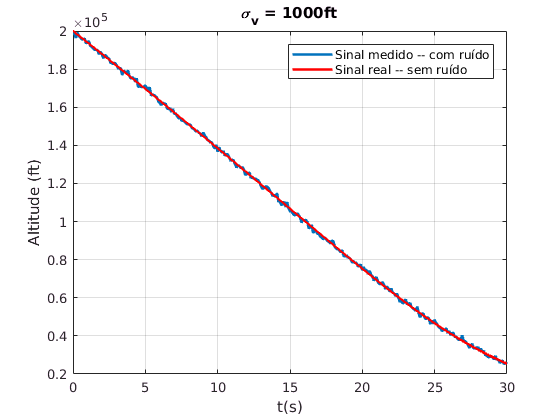

clear all; close all; clc;

%% ========================================================================
%
% 1. Definição inicial das variáveis; e
% 2. Inserção de ruído na variável a ser amostrada.
%
% =========================================================================

% Tempo total de simulação e variáveis de passo de integração.
h      = 0.001;
Ttotal = 30;
Ts     = 0.1;
t      = linspace(0, Ttotal, (Ttotal)/h + 1);  

% Parâmetros iniciais da nossa simulação (altitude e velocidade iniciais).
X{1} = [200000; -6000];

% Coeficiente de arrasto e constante gravitacional.
beta = 500;
g    = 32.2;

% Por meio da equação não-linear da queda de um corpo submetido à gravidade
% e um arrasto com coeficiente de arrasto constante, a gente integra a
% dinâmica e encontraremos a dinâmica da posição e velocidade.
for k = 1:max(size(t))
    % ==============================================================
    % As equações de Runge-Kuta de 2º ordem são simplificarmente, 
    % expressas por meio de:
    %
    %     c1 = f(x, t);
    %     c2 = f(x, t + h);
    %    
    %     x(k+1) = x(k) + (1/2)*h*(c1 + c2);
    % 
    % O que a gente tentará fazer aqui é reproduzir isso no inline.
    % ==============================================================
    
    % Pega os valores da estrutura 'x' (para condensar os resultados).
    x(1) = X{k}(1,1);
    x(2) = X{k}(2,1);
      
    % Cálculo de c1.
    x_d    = zeros(2,1);   
      
    x_d(1) = x(2);
    x_d(2) = 0.0034*g*exp(-x(1)/22000)*(x(2)^2)/(2*beta) - g;
    
    c1     = [x_d(1);
              x_d(2)];
        
    % Cálculo de c2 -- Nosso caso não depende do tempo.
    x_d = zeros(2,1);
      
    x_d(1) = x(2);
    x_d(2) = 0.0034*g*exp(-x(1)/22000)*(x(2)^2)/(2*beta) - g; 
    
    c2     = [x_d(1);
              x_d(2)];
    
    % Dinâmica 'final'.
    X{k+1} = X{k} + (1/2)*h*(c1 + c2);
end

% Conforme descrito, para o referido exemplo o ruído de medida apresenta um
% desvio padrão de 1000 e média zero (variável de saída).
desvio_padrao = 1000;
ruido         = 0 + desvio_padrao*randn(1 + (Ttotal/Ts),1);

% A medida 'real' do radar (ou seja, a realidade + ruído).
H  = [1 0];
j  = 0;
for k = 1:max(size(t))
   
   if (mod(t(k), Ts) == 0)
       % Atualiza o contador e o tempo discreto.
       j     = j + 1;
       td(j) = (j-1)*Ts;
       
       % Saída amostrada
       z(j)  = H*X{k} + ruido(j); 
   end
   
   % Altitude.
   x(k) = X{k}(1,1);
end

% Plota o sinal real (em vermelho) e o sinal com ruído (azul).
plot(td, z, 'Linewidth', 2); hold on;
plot(t, x, 'r', 'Linewidth', 2); grid;
xlabel('t(s)');
ylabel('Altitude (ft)');
title('\sigma_{v} = 1000ft');
legend('Sinal medido -- com ruído', 'Sinal real -- sem ruído');

## Setagem inicial de preparação para o Filtro de Kalman Estendido

% Inicialmente, vamos falar que existe um 'match' perfeito entre a dinâmica
% real e o nosso modelo matemático. Para nosso primeiro exemplo, faremos:
u_s  = 0;

% Em consequência, tem-se que:
w     = [0; 
         u_s];
PSI_s = u_s^2;

% Matriz identidade de ordem 2x2.
I = eye(2);

% O ruído de medida é o do próprio radar. No instante inicia k = 1, tem-se:
R{1}  = desvio_padrao^2;

Matriz de Covariância no instante inicial.

% Inicializando a 'Matriz de Covariância' do nosso sistema.
P{1}(1,1) = desvio_padrao^2;
P{1}(2,2) = 20000;
P0        = P{1};

Melhores estimativas iniciais para os estados.

x_hat(1)  = 200025;
xd_hat(1) = -6150;

% Vetor de estados
X_hat{1}  = [x_hat(1);
             xd_hat(1)];

## Aplicação da Recursão

Em cima do equacionamento a partir da linearização dos sistema, em que:


$$F\left(t\right)=\left\lbrack \begin{array}{c}
0 & 1\\
-\frac{\text{ }0,0034{\text{ge}}^{\frac{{-x}_1 }{22000}} x_2^2 }{44000\beta \text{ }} & \frac{\text{ }0,0034{\text{ge}}^{\frac{-x_1 }{22000}} x_2 }{\beta \text{ }}
\end{array}\right\rbrack$$


% Contador para os instantes de amostragem.
for k = 1:max(size(z))

    % Atualiza a escala de tempo.
    t_sample(k) = (k - 1)*Ts;
           
    % Qual é a melhor estimativa que temos do sinal no instante atual?
    X_hat_good_estimate{k} = X_hat{k};
      
    % Quebro a variável em variáveis individuais.
    x1_hat(k) = X_hat_good_estimate{k}(1,1);
    x2_hat(k) = X_hat_good_estimate{k}(2,1);
    
    % Determinação de f21 e f22.
    f21 = -(0.0034 * exp(-x1_hat(k)/22000) * g * x2_hat(k)^2)/ (44000 * beta);
    f22 =  (0.0034 * exp(-x1_hat(k)/22000) * g * x2_hat(k)  )/ (beta);
    

De posse de $f_{21}$ e $f_{22}$, temos de determinar quem que é a matriz $Q_k$.


$$Q_k =\Psi {\text{ }}_s \left\lbrack \begin{array}{c}
\frac{\text{ }T_s^3 }{3} & \left(\frac{\text{ }T_s^2 }{2}+f_{22} \frac{\text{ }T_s^3 }{3}\right)\\
\left(\frac{\text{ }T_s^2 }{2}+f_{22} \frac{\text{ }T_s^3 }{3}\right) & \left(T_s +f_{22} T_s^2 +{f_{22} }^2 \frac{\text{ }T_s^3 }{3}\right)
\end{array}\right\rbrack$$


    % Matriz de erros de estado Q{k}.
    % a) Primeira linha.
    q(1,1) = (Ts^3)/3;
    q(1,2) = (1/2)*(Ts^2) + (1/2) * f22 * (Ts^3);

    % b) Segunda linha.
    q(2,1) = (1/2)*(Ts^2) + (1/3) * f22 * (Ts^3);
    q(2,2) = Ts + f22*(Ts^2) + (1/3) * (f22^2) * (Ts^3);

    % Matriz 'Q{k}'.
    Q{k} = PSI_s*q;
    

A Matrix $R_k$ não muda, portanto:

    % Matriz 'R{k}'.
    % ==============
    R{k} = R{1};    

A outra matriz que precisa entrar nas equações de Riccati é a $\Phi_k$, que por meio da aproximação


$$\Phi_k \approx I+{F\text{T}}_s =\left\lbrack \begin{array}{c}
1 & T_s \\
f_{21} T_s  & \left(1+f_{22} T_s \right)
\end{array}\right\rbrack$$


é dada por:

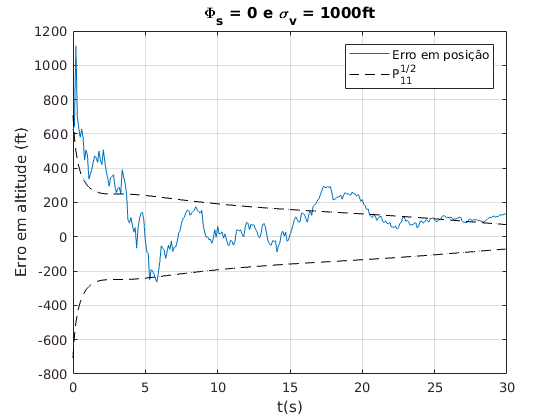

    % Matriz de estados atualizada (para utilização nas eq. de Riccati).
    % ==================================================================
    % a_ Primeira linha.
    phi_k(1,1) = 1;
    phi_k(1,2) = Ts;

    % b) Segunda linha.
    phi_k(2,1) = f21 * Ts;
    phi_k(2,2) = (1 + f22 * Ts);

    
    % Aproximação de Taylor das equaçõs de estados.
    PHI{k} = phi_k;

Com isso, a gente faz todo o cálculo necessário das equações de Riccati, a saber:


$$M_k = \Phi_{k}P_{k-1}\Phi_{k}^T + Q_k
$$



$$K_k = M_{k}C^T(CM_kC^T+R_k)^{-1}$$



$$P_k = (I-K_kC)M_k$$


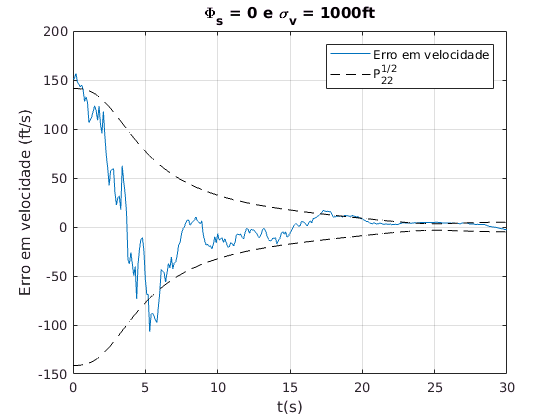

    % Determina-se a matriz de Kalman.
    % ================================
    if (k == 1)
        M{k} = PHI{k} * P0 * (PHI{k}') + Q{k}; 
        K{k} = M{k} * (H') * (H * M{k} * (H') + R{k})^(-1);
        P{k} = (I - K{k} * H) * M{k};
    else
        M{k} = PHI{k} * P{k-1} * (PHI{k}') + Q{k}; 
        K{k} = M{k} * (H') * (H * M{k} * (H') + R{k})^(-1);

        P{k} = (I - K{k} * H) * M{k};
    end

De posse dos dados apresentados, a gente procura melhorar a estimativa fazendo uso dos dados obtidos por meio da amostragem. Isso é realizado por meio de:


$${\hat{x} }^+ \left(k\right)=$$

$${\hat{x} }^- \left(k\right)+K\left\lbrack z\left(k\right)-H{\hat{x} }^- \left(k\right)\right\rbrack$$


em que:

- ${\hat{x} }^+ \left(k\right):$ é a melhor estimativa para o vetor de estados estimados **após** o filtro de Kalman para o instante **k -- (best estimate)**;

- ${\hat{x} }^- \left(k\right):$ é a melhor estimativa para o vetor de estados estimados até então disponível (ou seja, obtido por meio de integração numérica com base no vetor de estados estimados no instante **k-1**)** -- (good estimate)**;

- K: é a matriz de Kalman obtida; e

- $z\left(k\right):$ é a amostra no instante **k**.

    % A gente pode melhorar essa estimativa, por meio do Filtro de Kalman
    % Estentido.
    X_hat_best_estimate{k} = X_hat_good_estimate{k} + K{k}*(z(k) - H*X_hat_good_estimate{k});
    
    % Atualiza a estimação do vetor estado do sistema.
    X_hat{k}               = X_hat_best_estimate{k};

Observe que aqui eu integrarei para o próximo instante de amostragem utilizando o $T_s$.

    % Após essa atualização, a gente simplesmente realiza alguma integração numérica e 
    % determina qual seria a melhor estimativa do vetor de estados no próximo instante
    % subsequente.
    % c1 = f(X_hat{k}, t_sample(k));
    % c2 = f(X_hat{k}, t_sample(k) + Ts);   
    % X_hat{k+1} = X_hat{k} + (1/2)*Ts*(c1 + c2);
    
    % Pega os valores da estrutura 'x' (para condensar os resultados).
    xh(1) = X_hat{k}(1,1);
    xh(2) = X_hat{k}(2,1);
      
    % Cálculo de c1.
    xh_d    = zeros(2,1);   
      
    xh_d(1) = xh(2);
    xh_d(2) = 0.0034*g*exp(-xh(1)/22000)*(xh(2)^2)/(2*beta) - g;
    
    c1     = [xh_d(1);
              xh_d(2)];
        
    % Cálculo de c2 -- Nosso caso não depende do tempo.
    xh_d = zeros(2,1);
      
    xh_d(1) = xh(2);
    xh_d(2) = 0.0034*g*exp(-xh(1)/22000)*(xh(2)^2)/(2*beta) - g; 
    
    c2     = [xh_d(1);
              xh_d(2)];
    
    % Dinâmica 'final'.
    X_hat{k+1} = X_hat{k} + (1/2)*Ts*(c1 + c2);
end

Após a realização de todas os cálculos pertinentes, eu simplesmente ploto o resultado obtido.

% Cálculo da medida de erro do sistema.
% =====================================
i = 0;
for k = 1:(max(size(X))-1)
    if(mod(t(k), Ts) == 0)    
        i = i + 1;
        
        erro{i} = X{k} - X_hat{i};
        
        % Erro em distância e velocidade.
        dist(i) = erro{i}(1,1);
        vel(i)  = erro{i}(2,1);
        
        % Matrizes p11 e p22.
        p11(i) = sqrt(P{i}(1,1));
        p22(i) = sqrt(P{i}(2,2));
    end
end

% Ajuste e plot do resultado.
% ===========================
% a) Erro em posição.
figure;
plot(t_sample, dist); 
hold on;
plot(t_sample, p11, '--k');
plot(t_sample, -p11, '--k');
grid;
xlabel('t(s)');
ylabel('Erro em altitude (ft)');
title('\Phi_s = 0 e \sigma_{v} = 1000ft');
legend('Erro em posição', 'P_{11}^{1/2}');

% b) Erro em velocidade.
figure;
plot(t_sample, vel);
hold on;
plot(t_sample, p22, '--k');
plot(t_sample, -p22, '--k');
grid;
xlabel('t(s)');
ylabel('Erro em velocidade (ft/s)');
title('\Phi_s = 0 e \sigma_{v} = 1000ft');
legend('Erro em velocidade', 'P_{22}^{1/2}');

A gente percebe que a estimativa do erro para a altitude fica dentro das predições (perceba que estão dentro dos limites de $\sqrt{\text{ }P_{11} }$) em aproximadamente 68% do tempo (valor correspondente a $\left.1\sigma \right)$. Equivalentemente a gente observa efeito similar para o erro de velocidade (perceba que estão dentro dos limites de $\sqrt{\text{ }P_{22} }$) em aproximadamente 68% do tempo (valor correspondente a $\left.1\sigma \right)$. Isso meio que nos faz aparentemente achar que o nosso filtro está funcionando perfeitamente.